   -1.3416   -0.4472    0.4472    1.3416

Elapsed time for computation: 0.013571 s


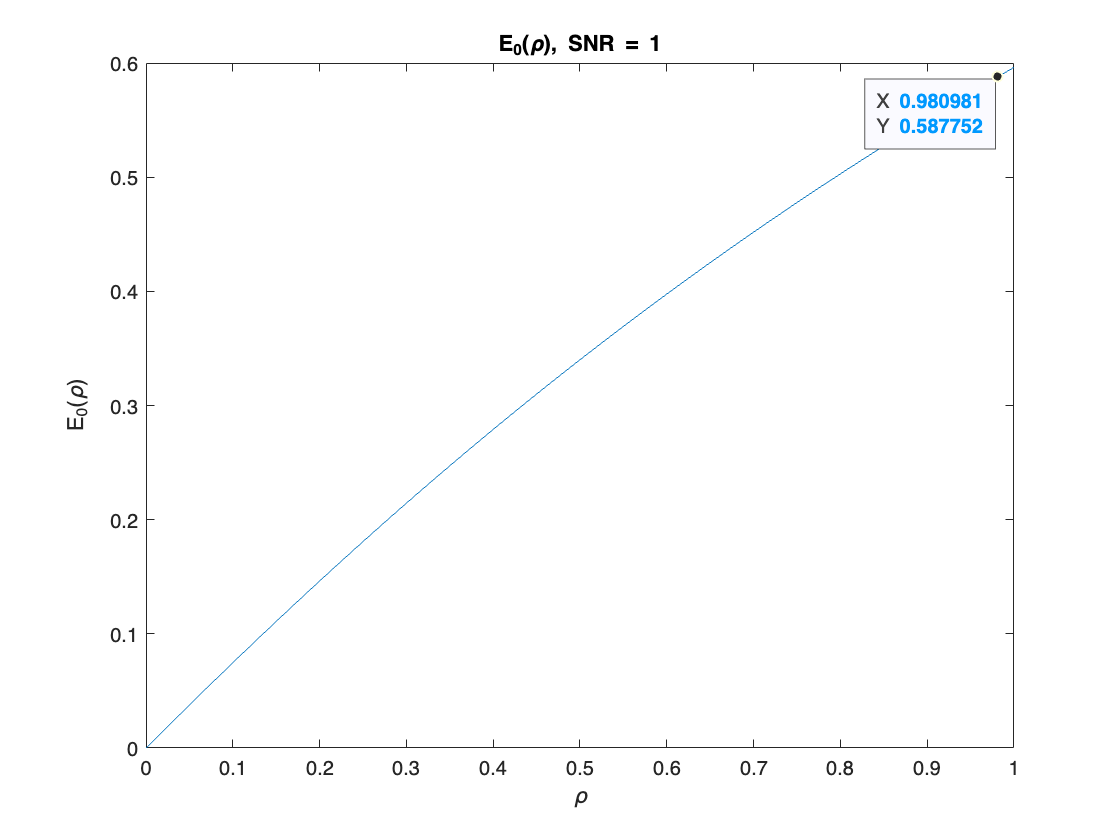

clear; clc;

function [rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points)
    % Gaussian PDF function
    G = @(z) (1/pi) * exp(-abs(z).^2);
    
    % Create complex quadrature nodes matrix
    N = length(nodes);
    z_matrix = createComplexNodesMatrix(nodes);
    
    % Create Pi matrix
    M = length(X);
    pi_matrix = createPiMatrix(M, N, weights);
    
    % Create G matrix
    g1_matrix = createGMatrix(X, z_matrix, SNR, G);
    
    % Compute rho values (always between 0 and 1)
    rho_values = linspace(0, 1, num_points);
    
    % Preallocate Eo_rho
    Eo_rho = zeros(size(rho_values));
    
    % Compute E0(rho) for different rho values
    tic;
    for idx = 1:length(rho_values)
        rho = rho_values(idx);
        
        % Compute intermediate terms
        g_powered = g1_matrix.^(1 / (1 + rho));
        qg_rho = Q * g_powered;
        qg_rho_t = qg_rho.^rho;
        pi_g_rho = pi_matrix .* (g1_matrix.^(-rho / (1 + rho)));
        
        % Combine results
        component_second = Q * (pi_g_rho * qg_rho_t');
        
        % Final calculation for E_0(rho)
        Eo_rho(idx) = -log2((1 / pi) * component_second);
    end
    time = toc;
    fprintf('Elapsed time for computation: %.6f s\n', time);
end

function z_matrix = createComplexNodesMatrix(nodes)
    % Create a matrix of complex quadrature nodes
    N = length(nodes);
    z_matrix = zeros(N, N);
    for i = 1:N
        for j = 1:N
            z_matrix(i,j) = nodes(i) + 1i*nodes(j);
        end
    end
end

function pi_matrix = createPiMatrix(M, N, weights)
    % Create Pi matrix with quadrature weights
    pi_matrix = zeros(M, N^2*M);
    pi_block = weights(1)*weights(2);
    for i = 1:M
        start_col = (i-1)*N^2 + 1;
        end_col = i*N^2;
        pi_matrix(i, start_col:end_col) = pi_block;
    end
end

function g1_matrix = createGMatrix(X, z_matrix, SNR, G)
    % Create G matrix based on constellation points and quadrature nodes
    M = length(X);
    N = size(z_matrix, 1);
    g1_matrix = zeros(M, N^2*M);
    
    for i = 1:M % Source symbols
        for j = 1:M % Received symbols
            for k = 1:N % First quadrature nodes
                for l = 1:N % Second quadrature nodes
                    % Compute column index
                    col_idx = (j-1)*N^2 + (k-1)*N + l;
                    
                    % Compute G values
                    g1_matrix(i, col_idx) = G(z_matrix(k,l) + (sqrt(SNR)*X(i)) - (sqrt(SNR)*X(j)));
                end
            end
        end
    end
end

function runBPSKAnalysis()
    M = 4;  % Number of constellation points
    amplitude = 3;  % Maximum amplitude
    
    X = linspace(-amplitude, amplitude, M);
    
    avg_energy = mean(X.^2);
    X = X / sqrt(avg_energy);
    
    disp(X);
    
    Q = ones(1, M) / M;
    
    nodes = [-1/sqrt(2), 1/sqrt(2)];
    weights = [sqrt(pi)/2, sqrt(pi)/2];
    
    SNR = 1;
    num_points = 1000;
    
    [rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points);
    
    figure;
    plot(rho_values, Eo_rho);
    xlabel('\rho');
    ylabel('E_0(\rho)');
    title(['E_0(\rho), SNR = ', num2str(SNR)]);
end

runBPSKAnalysis();